syms s t
syms a positive
% a라는 문자는 항상 양수임을 선언

%laplace(함수,함수독립변수,s)

f_a = 1; f_b = exp(-a*t);
f_c = t; f_d = dirac(t-a);
f_e = cos(t); f_f = t^2*exp(-a*t);
f_g  = exp(-a*t)*sin(t);

Fs_a = laplace(f_a,t,s)

$$Fs\_a = \frac{1}{s}$$

Fs_b = laplace(f_b,t,s)

$$Fs\_b = \frac{1}{a+s}$$

Fs_c = laplace(f_c,t,s)

$$Fs\_c = \frac{1}{s^{2}}$$

Fs_d = laplace(f_d,t,s)

$$Fs\_d = {\mathrm{e}}^{-a\,s}$$

Fs_e = laplace(f_e,t,s)

$$Fs\_e = \frac{s}{s^{2}+1}$$

Fs_f = laplace(f_f,t,s)

$$Fs\_f = \frac{2}{{\left(a+s\right)}^{3}}$$

Fs_g = laplace(f_g,t,s)

$$Fs\_g = \frac{1}{{\left(a+s\right)}^{2}+1}$$

clear all;

syms t tau f(t) s
syms a positive

dfdt=diff(f(t))

$$dfdt = \frac{\partial }{\partial t}f\left(t\right)$$

intf=int(subs(f(t),t,tau),tau,[0 t])

$$intf = \int_{0}^{t}f\left(\tau \right)\mathrm{d}\tau$$

fsft=exp(a*t)*f(t)

$$fsft = {\mathrm{e}}^{a\,t}\,f\left(t\right)$$

tsft=subs(f(t),t,t-a)*heaviside(t-a)

$$tsft = f\left(t-a\right)\,\mathrm{heaviside}\left(t-a\right)$$

%heaviside 유닛 스텝 함수와 같음.

Fs_dfdt=simplify(laplace(dfdt));
Fs_intf=simplify(laplace(intf));
Fs_fsft=simplify(laplace(fsft));
Fs_tsft=simplify(laplace(tsft));

syms F(s)

Fs_dfdt=subs(Fs_dfdt,laplace(f(t),t,s),F(s))

$$Fs\_dfdt = s\,F\left(s\right)-f\left(0\right)$$

Fs_intf=subs(Fs_intf,laplace(f(t),t,s),F(s))

$$Fs\_intf = \frac{F\left(s\right)}{s}$$

Fs_fsft=subs(Fs_fsft,laplace(f(t),t,s-a),F(s-a))

$$Fs\_fsft = F\left(s-a\right)$$

Fs_tsft=subs(Fs_tsft,laplace(f(t),t,s),F(s))

$$Fs\_tsft = {\mathrm{e}}^{-a\,s}\,F\left(s\right)$$

% 운동방정식 정의

clear all;

syms x(t) X t s

m=1; c=2; k=10; F=1;

eqn = m*diff(x(t),2)+c*diff(x(t))+k*x(t)==F

$$eqn = \frac{\partial^{2}}{\partial t^{2}}x\left(t\right)+2\,\frac{\partial }{\partial t}x\left(t\right)+10\,x\left(t\right)=1$$


%라플라스 변환
L_eqn = laplace(eqn);
L_eqn_final= subs(L_eqn,{laplace(x(t),t,s),x(0),subs(diff(x(t)),t,0)},{X,0,0})

$$L\_eqn\_final = X\,s^{2}+2\,X\,s+10\,X=\frac{1}{s}$$

X = solve(L_eqn_final,X)

$$X = \frac{1}{s^{3}+2\,s^{2}+10\,s}$$

%라플라스 역변환

syms x
x=ilaplace(X)

$$x = \frac{1}{10}-\frac{{\mathrm{e}}^{-t}\,\left(\cos\left(3\,t\right)+\frac{\sin\left(3\,t\right)}{3}\right)}{10}$$

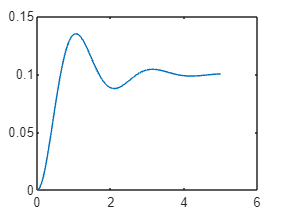

% 그래프 그리기
t_=linspace(0,5,150);
plot(t_,subs(x,t,t_))

%TF 정의
clear all;

syms x(t) u(t) X U t s
m=1;c=2;k=10;

eqn_1 = m*diff(x(t),2)+c*diff(x(t))+k*x(t)==u;

L_eqn_1 = laplace(eqn_1);
L_eqn_1_final=subs(L_eqn_1,{laplace(x(t),t,s),laplace(u(t),t,s),x(0),subs(diff(x(t)),t,0)},{X,U,0,0})

$$L\_eqn\_1\_final = X\,s^{2}+2\,X\,s+10\,X=U$$

X=solve(L_eqn_1_final,X)

$$X = \frac{U}{s^{2}+2\,s+10}$$

TF=X/U

$$TF = \frac{1}{s^{2}+2\,s+10}$$


[n,d]=numden(TF)

$$n = 1$$

$$d = s^{2}+2\,s+10$$

a = sym2poly(n)

a = 1

b = sym2poly(d)

b =      1     2    10


sys = tf(a,b)

sys =
 
        1
  --------------
  s^2 + 2 s + 10
 
연속시간 전달 함수입니다.
모델 속성


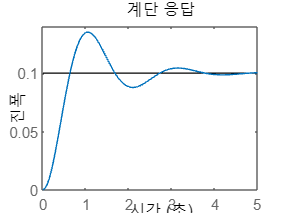

step(sys,5)